Fuzzy Logic Home EMS controller

Load Siulink Model

cd C:\dev\WPS3-EMS\FuzzyLogicController\
model = 'Training_Model_compactHEMS';
%load_system(model)
%out_Hems = sim(model)
%plot_results_HEMS(out_Hems)

## Create FIS Tree Controller Structure

% If already have a Fis use
% fis_Current = readfis(fileName)


% Define membership function names for the input variables.
% Input MF of variables
mf_SOC = ["Min","Low","Medium","High","Max"]; % Low, Medium, High
mf_Pnet = ["RES>>","Load>>"]; % [- 0 +] P_net = P_Load-P_RES :: Negative (High PV), Zero, Positive (High Load)
mf_Price = ["Low","Medium","High"]; % Low , High
% Output MF
mf_Pbatt = ["CH","HOLD","DC"]; % % [- 0 +] 

clear fis_Current

% Create first FIS.
fis_Current = mamfis('Name','FIS Current','NumInputs',3,'NumOutputs',1, ...
    'NumInputMFs',[length(mf_SOC) length(mf_Pnet) length(mf_Price)],'NumOutputMFs',length(mf_Pbatt));
% convert to Sugeno 
fis_Current = convertToSugeno(fis_Current);

% Configure input and output variables.
% Input 1 SOC
SOC_range = [battery_min_soc battery_max_soc];
SOC_mid = (SOC_range(1)+SOC_range(2))/2;
fis_Current = updateInput(fis_Current,1,'SOC',SOC_range , mf_SOC);
fis_Current.Inputs(1).MembershipFunctions(1).Type = 'linzmf';% MIN
fis_Current.Inputs(1).MembershipFunctions(1).Parameters = [SOC_range(1) SOC_range(1)+1];
fis_Current.Inputs(1).MembershipFunctions(2).Type = 'trimf'; %LOW
fis_Current.Inputs(1).MembershipFunctions(2).Parameters = [SOC_range(1)  SOC_range(1)+15 SOC_range(1)+30];
fis_Current.Inputs(1).MembershipFunctions(3).Type = 'trimf'; % MED
fis_Current.Inputs(1).MembershipFunctions(3).Parameters = [SOC_mid-20 SOC_mid SOC_mid+20];
fis_Current.Inputs(1).MembershipFunctions(4).Type = 'trimf'; % HIGH
fis_Current.Inputs(1).MembershipFunctions(4).Parameters = [SOC_range(2)-30 SOC_range(2)-15 SOC_range(2)];
fis_Current.Inputs(1).MembershipFunctions(5).Type = 'linsmf'; % MAX
fis_Current.Inputs(1).MembershipFunctions(5).Parameters = [SOC_range(2)-1 SOC_range(2)];

clear SOC_mid SOC_range

% Input 2 Net Power
Net_power_range = [-1 1] ;%  
fis_Current = updateInput(fis_Current,2,'Pnet',Net_power_range*50, mf_Pnet); 
fis_Current.Inputs(2).MembershipFunctions(1).Type = 'linzmf';  % RES>>
fis_Current.Inputs(2).MembershipFunctions(1).Parameters = [Net_power_range(1) 0.1];
fis_Current.Inputs(2).MembershipFunctions(2).Type = 'linsmf'; % Load>>
fis_Current.Inputs(2).MembershipFunctions(2).Parameters = [-0.1 Net_power_range(2)];

% Input 3 price
fis_Current = updateInput(fis_Current,3,'Price',[-0.6 0.6],mf_Price);
fis_Current.Inputs(3).MembershipFunctions(1).Type = 'linzmf';% Low
fis_Current.Inputs(3).MembershipFunctions(1).Parameters = [-0.5 0];
fis_Current.Inputs(3).MembershipFunctions(2).Type = 'trimf'; % MED
fis_Current.Inputs(3).MembershipFunctions(2).Parameters = [-0.3 0 0.3];
fis_Current.Inputs(3).MembershipFunctions(3).Type = 'linsmf'; % High
fis_Current.Inputs(3).MembershipFunctions(3).Parameters = [0 0.5];


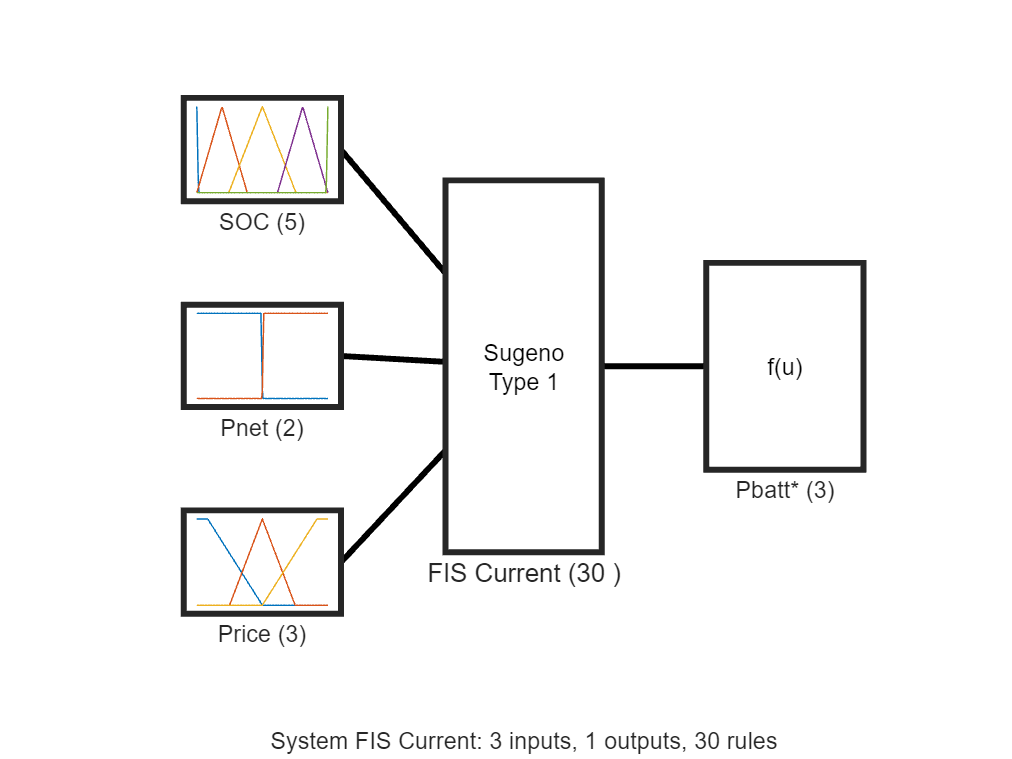

% Output 1
Batt_power_range = [-1 1]; % or  [-battery_max_charge battery_max_discharge]

sugeno =  true;

if sugeno
    % Sugeno Output
    fis_Current = updateOutput(fis_Current,1,'Pbatt*', Batt_power_range, mf_Pbatt);
    fis_Current.Output(1).MembershipFunctions(1).Type = 'constant';
    fis_Current.Output(1).MembershipFunctions(1).Parameters = [Batt_power_range(1)];
    fis_Current.Output(1).MembershipFunctions(2).Type = 'constant';
    fis_Current.Output(1).MembershipFunctions(2).Parameters = [0];
    fis_Current.Output(1).MembershipFunctions(3).Type = 'constant';
    fis_Current.Output(1).MembershipFunctions(3).Parameters = [Batt_power_range(2)];
else
    %Mangani
    fis_Current = updateOutput(fis_Current,1,'Pbatt*', Batt_power_range, mf_Pbatt);
    fis_Current.Output(1).MembershipFunctions(1).Type = 'linzmf';
    fis_Current.Output(1).MembershipFunctions(1).Parameters = [Batt_power_range(1) 0];
    fis_Current.Output(1).MembershipFunctions(2).Type = 'trimf';
    fis_Current.Output(1).MembershipFunctions(2).Parameters = [-0.1 0.1];
    fis_Current.Output(1).MembershipFunctions(3).Type = 'linsmf';
    fis_Current.Output(1).MembershipFunctions(3).Parameters = [0 Batt_power_range(2)];
end

figure
plotfis(fis_Current)

Add Rules

Format:    **IF** (antecedent) **THEN** (consequent)

% Clear all Rules
fis_Current.Rules = [];

% Add the rules to the FIS.
rule1 = "If SOC is Min and Pnet is RES>> then Pbatt* is CH";
rule2 = "If SOC is Max and Pnet is Load>> then Pbatt* is DC";
rule3 = "If SOC is Max and Pnet is RES>> then Pbatt* is HOLD";
rule4 = "If SOC is Min and Pnet is Load>> then Pbatt* is HOLD";

rule5 = "If SOC is Low and Pnet is RES>> then Pbatt* is CH";
rule6 = "If SOC is Medium and Pnet is RES>> then Pbatt* is CH";
rule7 = "If SOC is High and Pnet is RES>> then Pbatt* is CH";

rule8 = "If SOC is Low and Pnet is Load>> and Price is Low then Pbatt* is HOLD"; % !
rule9 = "If SOC is Medium and Pnet is Load>> and Price is Low then Pbatt* is HOLD"; % !
rule10 = "If SOC is High and Pnet is Load>> and Price is Low then Pbatt* is DC"; % !
%%%%%%
rule11 = "If SOC is Low and Pnet is Load>> and Price is Medium then Pbatt* is HOLD"; % !
rule12 = "If SOC is Medium and Pnet is Load>> and Price is Medium then Pbatt* is DC"; % !
rule13 = "If SOC is High and Pnet is Load>> and Price is Medium then Pbatt* is DC"; % !

rule14 = "If SOC is Low and Pnet is Load>> and Price is High then Pbatt* is DC"; % !
rule15 = "If SOC is Medium and Pnet is Load>> and Price is High then Pbatt* is DC"; % !
rule16 = "If SOC is High and Pnet is Load>> and Price is High then Pbatt* is DC"; % !

rules = strings(1, 16); % ADD ALL Predefined Rules 

for i = 1:size(rules,2)
    rulenumber = sprintf('rule%d', i);
    rules(i) = eval(rulenumber);
end
fis_Current = addRule(fis_Current,rules);
%showRuleBase(fis_Current) % Works only for 2 inputs

Add Second Fis if wanted

secondFIS = false;

if secondFIS
    % input MF
    mf_Pbatt2 = ["CH","Hold","DC"]; % 
    mf_Load_pred = ["0","+","++"];
    mf_PV_pred = ["0","+","++"];
    % Output MF
    % same P_Batt as input
    
    % Create second FIS.
    fis_Pred = mamfis('Name','FIS Predictions','NumInputs',3,'NumOutputs',1, ...
        'NumInputMFs',[length(mf_Pbatt2) length(mf_Load_pred) length(mf_PV_pred)],'NumOutputMFs',length(mf_Pbatt2) );
    
    % Configure input and output variables.
    fis_Pred = updateInput(fis_Pred,1,'Pbatt*',[-battery_max_charge battery_max_discharge],mf_Pbatt2);
    fis_Pred = updateInput(fis_Pred,2,'Load prediction',[0 5],mf_Load_pred);
    fis_Pred = updateInput(fis_Pred,3,'PV prediction',[0 5],mf_PV_pred);
    fis_Pred = updateOutput(fis_Pred,1,'Pbatt',[-battery_max_charge battery_max_discharge],mf_Pbatt2);
    
    % Plot Fis 2
    figure
    plotfis(fis_Pred)

Combine `fis1` and `fis2` into a FIS tree structure.

    connection = [fis_Current.Name + "/" + fis_Current.Outputs(1).Name ...
        fis_Pred.Name + "/" + fis_Pred.Inputs(1).Name];
    fisTInit = fistree([fis_Current fis_Pred],connection);
    
    figure
    plotfis(fisTInit)
else
    fisTInit = fis_Current;
end

## Analyze and Modify Rule Base

To visualize the behavior of the tuned rule base, plot the control surface of each fuzzy system in the FIS tree.

Rulescheck = false;
if Rulescheck
    fig_controlSurface_Fis1 = figure;
    gensurf(fis_Current(1))
    title('Control Surface')
end

% Safe Figures?
save_figures = false;

if save_figures
    ResultsFolder = './Results/';
    figwidth = 6; % width in inches (adjust this)
    figheight = 4; % height in inches (adjust this)
    saveas(fig_controlSurface_Fis1,  append(ResultsFolder ,'controlSurface_FIS1','epsc'))
    saveas(fig_controlSurface_Fis1,  append(ResultsFolder ,'controlSurface_FIS1','pdf'))
    disp('Figures saved as PDF and eps')
end

## Tune Controller Rules

Once you have a FIS tree structure, you can optimize the controller behavior by tuning the rules and MF parameters of the component FIS objects. To do so, you can use the `tunefis` function.

In general, uniformly distributed MFs provide a meaningful initial condition for tuning a fuzzy system. Therefore, as an initial tuning step, you can learn the rules of the FIS objects while keeping their default MF parameters.

To learn the rules, first get the tunable settings from the fuzzy systems.

[in,out,rule] = getTunableSettings(fisTInit);

Next, update the rule settings to optimize only the rule consequents. By doing so, you keep the existing rule antecedents, which already include all possible input MF combinations for their corresponding FIS inputs.

% Set Tuning  Rules Custom  
rule(1:7) = setTunable(rule(1:7),false); % Do NOT TUNE These Rules

% Tune only input 3 and output of the new rules
for rId = 8:numel(rule)
    rule(rId).Antecedent.Free(1,1:2) = false; 
    rule(rId).Antecedent.AllowEmpty(1,3) = true;
    rule(rId).Antecedent.AllowNot(1,3) = true;
    rule(rId).Consequent.Free = true;
    rule(rId).Consequent.AllowEmpty = true;
    
end

Create an option set for the tuning process.

options =  tunefisOptions("OptimizationType","tuning","Method","patternsearch");

Methods: "`ga"` (default) | `"particleswarm"` | `"patternsearch"` | `"simulannealbnd"` | `"anfis"`

`OPtimisation Type: "tuning"` (default) | `"learning"`

Use the default genetic algorithm tuning method for learning the rules. Set the maximum number of generations to 3 and use a population size of 100.

%options.MethodOptions.MaxGenerations = 3;
%options.MethodOptions.PopulationSize = 100;

### Cost Function

Next, create a cost function to evaluate each candidate rule base. At the end of the optimization process, the rule base with the minimum cost is selected for the fuzzy systems in the FIS tree.


$$\textrm{Cost}=\sum_t P_{\textrm{Grid}} \left(t\right)*\textrm{Price}\left(t\right)$$


Using this cost function, the tuning process selects rule bases that maintain a normal condition and avoid cost. Also, the high Cost values used in step 2 help discard rule bases that overstep a certain boudary (Punishment).

%Pgrid = Pnet - Pbatt % P_net == (P_Load - P_PV) = P_batt + P_grid
%cost = sum(Pgrid*Price)

Tuning is a time-consuming process!

minData = MinCostModel;

wsVars = ["fisT"];
rng('default') % random number generator

% Tuning FIS    
fisTRuleTuned = tunefis(fisTInit,rule,...
    @(fis)costFcn(fis,model,wsVars,minData),options);

cost = 4.4942

Minimum cost = 4.494243

cost = 13.2208

Minimum cost = 4.494243

cost = 15.3895

Minimum cost = 4.494243

cost = 11.7192

Minimum cost = 4.494243

cost = 12.8820

Minimum cost = 4.494243

cost = 7.5311

Minimum cost = 4.494243

cost = 9.8067

Minimum cost = 4.494243

cost = 9.0446

Minimum cost = 4.494243

cost = 15.7342

Minimum cost = 4.494243

cost = 7.4672

Minimum cost = 4.494243

cost = 12.5136

Minimum cost = 4.494243

cost = 14.6382

Minimum cost = 4.494243

cost = 10.4979

Minimum cost = 4.494243

cost = 13.0421

Minimum cost = 4.494243

cost = 15.9883

Minimum cost = 4.494243

cost = 8.6191

Minimum cost = 4.494243

cost = 12.2808

Minimum cost = 4.494243

cost = 13.4204

Minimum cost = 4.494243

cost = 12.5388

Minimum cost = 4.494243

cost = 13.4056

Minimum cost = 4.494243

cost = 10.9503

Minimum cost = 4.494243

cost = 7.6343

Minimum cost = 4.494243

cost = 10.6096

Minimum cost = 4.494243

cost = 13.2455

Minimum cost = 4.494243

cost = 12.9242

Minimum cost = 4.494243

cost = 9.4638

Minimum cost = 4.494243

cost = 9.4008

Minimum cost = 4.494243

cost = 12.7755

Minimum cost = 4.494243

cost = 9.8387

Minimum cost = 4.494243

cost = 11.4632

Minimum cost = 4.494243

cost = 7.1295

Minimum cost = 4.494243

cost = 12.4952

Minimum cost = 4.494243

cost = 8.4551

Minimum cost = 4.494243

cost = 9.7033

Minimum cost = 4.494243

cost = 10.3308

Minimum cost = 4.494243

cost = 13.0416

Minimum cost = 4.494243

cost = 12.0334

Minimum cost = 4.494243

cost = 7.6484

Minimum cost = 4.494243

cost = 12.3430

Minimum cost = 4.494243

cost = 12.1721

Minimum cost = 4.494243

cost = 12.1334

Minimum cost = 4.494243

cost = 10.5681

Minimum cost = 4.494243

cost = 10.7226

Minimum cost = 4.494243

cost = 11.0719

Minimum cost = 4.494243

cost = 9.7961

Minimum cost = 4.494243

cost = 14.6778

Minimum cost = 4.494243

cost = 9.5034

Minimum cost = 4.494243

cost = 10.7890

Minimum cost = 4.494243

cost = 12.2003

Minimum cost = 4.494243

cost = 12.0847

Minimum cost = 4.494243

cost = 8.1698

Minimum cost = 4.494243

cost = 8.1741

Minimum cost = 4.494243

cost = 10.2581

Minimum cost = 4.494243

cost = 12.2645

Minimum cost = 4.494243

cost = 10.6407

Minimum cost = 4.494243

cost = 9.7915

Minimum cost = 4.494243

cost = 12.1926

Minimum cost = 4.494243

cost = 12.6010

Minimum cost = 4.494243

cost = 7.6207

Minimum cost = 4.494243

cost = 16.7073

Minimum cost = 4.494243

cost = 10.0112

Minimum cost = 4.494243

cost = 12.8208

Minimum cost = 4.494243

cost = 10.8110

Minimum cost = 4.494243

cost = 7.7124

Minimum cost = 4.494243

cost = 12.8383

Minimum cost = 4.494243

cost = 9.3197

Minimum cost = 4.494243

cost = 16.5275

Minimum cost = 4.494243

cost = 13.1053

Minimum cost = 4.494243

cost = 10.1576

Minimum cost = 4.494243

cost = 11.6412

Minimum cost = 4.494243

cost = 13.0182

Minimum cost = 4.494243

cost = 9.9235

Minimum cost = 4.494243

cost = 12.6817

Minimum cost = 4.494243

cost = 10.0664

Minimum cost = 4.494243

cost = 13.0131

Minimum cost = 4.494243

cost = 11.2912

Minimum cost = 4.494243

cost = 8.5710

Minimum cost = 4.494243

cost = 10.0190

Minimum cost = 4.494243

cost = 11.4791

Minimum cost = 4.494243

cost = 12.5066

Minimum cost = 4.494243

cost = 12.2090

Minimum cost = 4.494243

cost = 12.0714

Minimum cost = 4.494243

cost = 14.0930

Minimum cost = 4.494243

cost = 11.4728

Minimum cost = 4.494243

cost = 12.0761

Minimum cost = 4.494243

cost = 6.9879

Minimum cost = 4.494243

cost = 11.1011

Minimum cost = 4.494243

cost = 8.7670

Minimum cost = 4.494243

cost = 15.0687

Minimum cost = 4.494243

cost = 8.0565

Minimum cost = 4.494243

cost = 9.3430

Minimum cost = 4.494243

cost = 12.0896

Minimum cost = 4.494243

cost = 12.6194

Minimum cost = 4.494243

cost = 15.3390

Minimum cost = 4.494243

cost = 17.0512

Minimum cost = 4.494243

cost = 10.5991

Minimum cost = 4.494243

cost = 10.5518

Minimum cost = 4.494243

cost = 11.1731

Minimum cost = 4.494243

cost = 8.5614

Minimum cost = 4.494243

cost = 12.2227

Minimum cost = 4.494243
                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0             100           4.494           11.29        0


cost = 11.1237

Minimum cost = 4.494243

cost = 9.0947

Minimum cost = 4.494243

cost = 14.0176

Minimum cost = 4.494243

cost = 5.1992

Minimum cost = 4.494243

cost = 5.7001

Minimum cost = 4.494243

cost = 8.7196

Minimum cost = 4.494243

Simulate the model using the FIS tree with tuned rule bases.

fisT = fisTRuleTuned;
ruleTunedOutput = sim(model);

Plot the result

##   HELPER FUNCTION

function fis = updateInput(fis,id,name,range,mfNames)
% Update FIS input with the specified parameter values.

fis.Inputs(id).Name = name;
fis.Inputs(id).Range = range;

for mfId = 1:length(mfNames)
    fis.Inputs(id).MembershipFunctions(mfId).Name = mfNames(mfId);
    params = range(1) + ...
        diff(range)*fis.Inputs(id).MembershipFunctions(mfId).Parameters;
    fis.Inputs(id).MembershipFunctions(mfId).Parameters = params;
end

end

function fis = updateOutput(fis,id,name,range,mfNames)
% Update FIS output with the specified parameter values.

rangeDiff = diff(range);
fis.Outputs(id).Name = name;

% MF names - Very Low, Low, Medium, High, Very High
%mfNames = ["VL","L","M","H","VH"];

for mfId = 1:length(mfNames)
    fis.Outputs(id).MembershipFunctions(mfId).Name = mfNames(mfId);
    params = range(1) + ...
        rangeDiff*fis.Outputs(id).MembershipFunctions(mfId).Parameters;
    fis.Outputs(id).MembershipFunctions(mfId).Parameters = params;
end

% Extend output range values to fit the output MFs.
left = fis.Outputs(id).MembershipFunctions(1).Parameters(1);
right = fis.Outputs(id).MembershipFunctions(end).Parameters(end);
fis.Outputs(id).Range = [left right];

end
